# ***IBME- CA1 - Amirmortaza Rezaee - 810101429***

# **2-1**

**Defining initial values and solving ODE's using ODE45:**

m=0.05;
n=0.35; 
h=0.65; 
vars=[n,m,h];
v_range = [-70, 20];

[v, y] = ode45(@findm,v_range,vars);

the_n=y(:,1);
the_m=y(:,2);
the_h=y(:,3);

**plotting the results:**

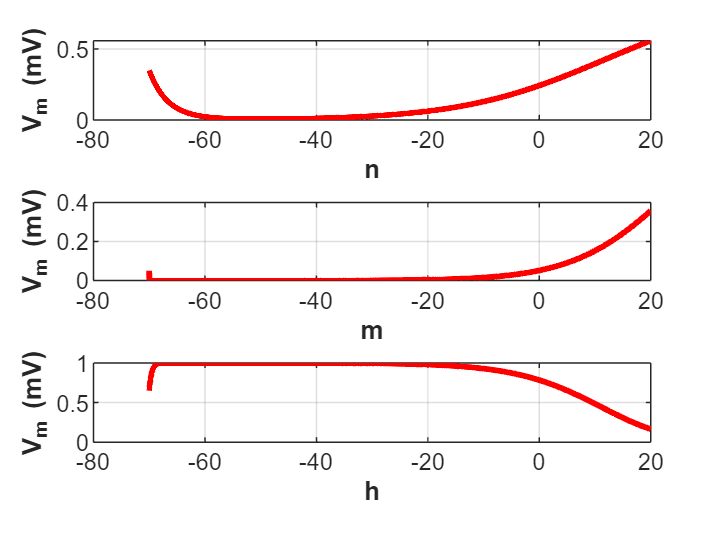

figure;
subplot(3,1,1);
plot(v, the_n, 'r', 'LineWidth', 2);
hold on;
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('n', 'FontWeight', 'bold');
grid on;

subplot(3,1,2);
plot(v, the_m, 'r', 'LineWidth', 2);
hold on;
ylabel('V_m (mV)', 'FontWeight','bold');
xlabel('m', 'FontWeight','bold');
grid on;

subplot(3,1,3);
plot(v, the_h, 'r', 'LineWidth', 2);
hold on;
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('h', 'FontWeight','bold');
grid on;

- **m**** and ****n** increase because both the sodium and potassium channels open as the membrane depolarizes. This enables the ions to flow through the membrane, leading to the action potential's rising phase (for sodium) and repolarization phase (for potassium).

- **h** decreases because the sodium channels begin to inactivate as the membrane potential becomes more positive, stopping further sodium entry and contributing to the action potential’s falling phase.

# **2_2:**

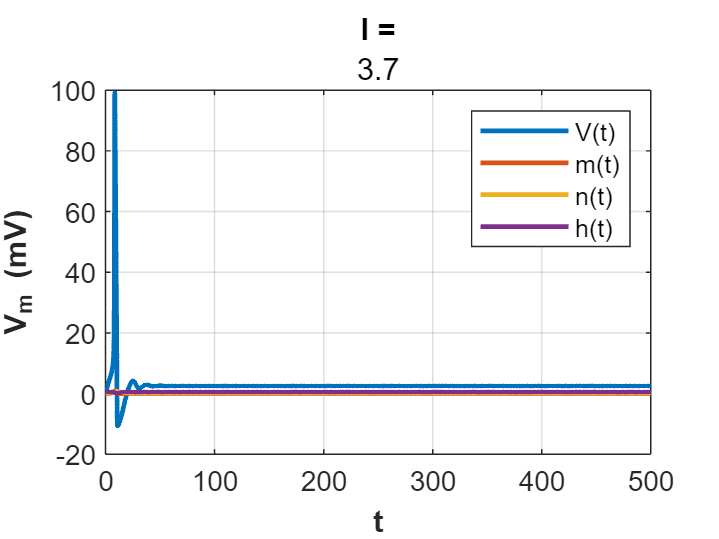

v0=0.0;
m0=0.05;
n0=0.35; 
h0=0.65; 
vars=[v0,n0,m0,h0];
the_time = 0:1e-3:500;
timespan = [0, max(the_time)];
I_stim1=3.7;
[t1, y1] = ode45(@(t,y)unit_step(t,y,I_stim1),timespan,vars);

the_v1=y1(:,1);
the_n1=y1(:,2);
the_m1=y1(:,3);
the_h1=y1(:,4);

figure;
plot(t1, [the_v1, the_m1, the_n1, the_h1], 'LineWidth', 1.6);
title('I =', I_stim1);
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
legend('V(t)','m(t)','n(t)', 'h(t)');
grid on;

the least domain of the unit step input, should be **3.7** to produce a spike in the output!

# **2_3:**

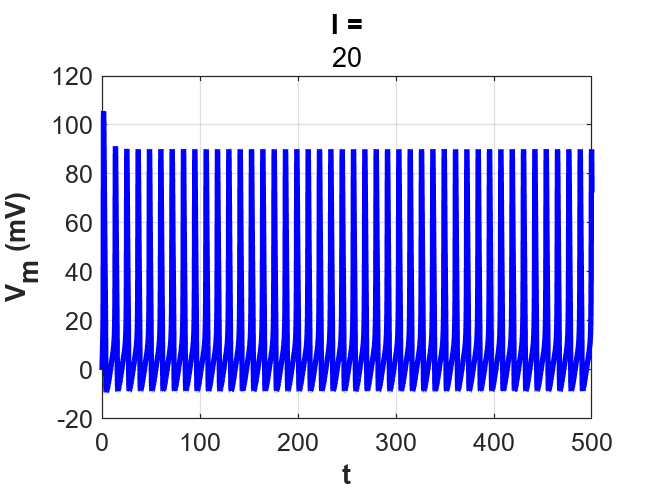

I_stim2=20;
[t2, y2] = ode45(@(t,y)unit_step(t,y,I_stim2),timespan,vars);

the_v2=y2(:,1);

figure;
plot(t2, the_v2, 'b', 'LineWidth', 2);
title('I =',I_stim2);
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;


refractory_period = 2*(305.275 - 303)/3;
disp('Refrectory period  = ');

Refrectory period  = 


disp(refractory_period) 

    1.5167



**Definition**: During the absolute refractory period, a neuron or excitable cell cannot generate a new action potential, no matter how strong the stimulus is.

It was measured as the initial 2/3 after the spike!

# **2_4:**

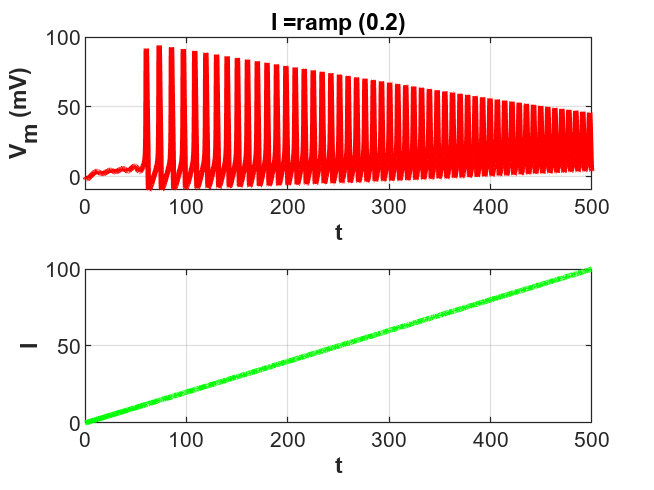

I_stim3=0.2;
[t3, y3] = ode45(@(t,y)ramp(t,y,I_stim3),timespan,vars);

the_v3=y3(:,1);

figure;
subplot(2,1,1);
plot(t3, the_v3, 'r', 'LineWidth', 2);
title('I =ramp (0.2)');
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

subplot(2,1,2);
plot(t3, I_stim3*t3, 'g', 'LineWidth', 2);
ylabel('I', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

Neurons typically rest at their **resting potential**. When a gradually increasing current or voltage (such as a ramp input) is applied to the neuron, the membrane potential gradually depolarizes. This increase in membrane potential eventually reaches a certain **threshold potential** at which an **action potential** is triggered.

**Tonic firing** refers to a state where the neuron fires action potentials continuously or repeatedly when subjected to a constant stimulus, such as a steady input current (often a ramp or constant current).

For tonic firing to occur, the input must be strong enough to keep the neuron in a state where it continuously reaches the threshold and generates action potentials.

# **2_5:**

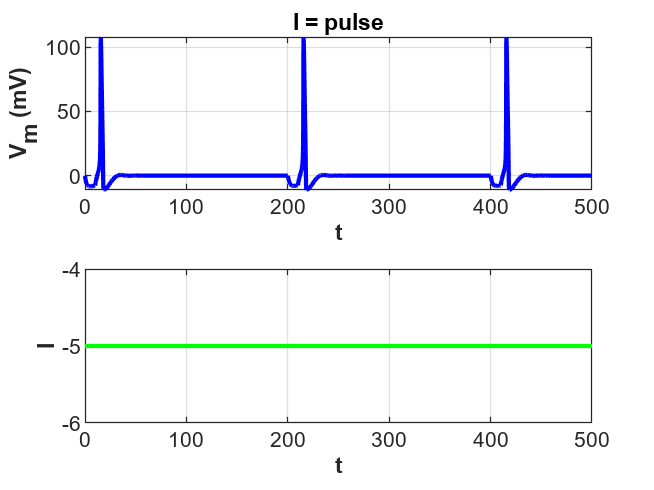

I_stim4=-5;
[t4, y4] = ode45(@(t,y)pulse(t,y,I_stim4),timespan,vars);

the_v4=y4(:,1);
 I_4 = ones(size(t4));
 I_4 = I_stim4* I_4;

figure;
subplot(2,1,1);
plot(t4, the_v4, 'b', 'LineWidth', 1.6);
title('I = pulse');
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

subplot(2,1,2);
plot(t4, I_4, 'g', 'LineWidth', 1.6);
ylabel('I', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

# **2_6:**

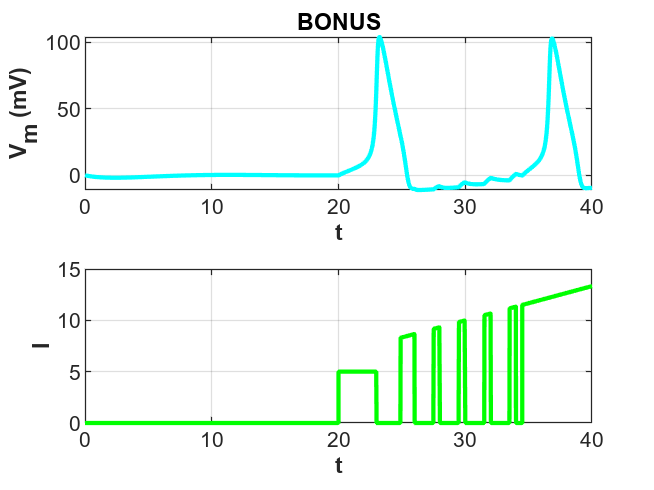

[t6, y6] = ode45(@(t,y)bonus(t,y),[0 40],vars);

the_v6=y6(:,1);
the_I = zeros(size(t6));
for i = 1:size(t6)
    the_I(i)= find_I(t6(i));
end

figure;
subplot(2,1,1);
plot(t6, the_v6, 'c', 'LineWidth', 1.6);
title('BONUS');
ylabel('V_m (mV)', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

subplot(2,1,2);
plot(t6, the_I, 'g', 'LineWidth', 1.6);
ylabel('I', 'FontWeight', 'bold');
xlabel('t', 'FontWeight', 'bold');
grid on;

**ODE's for complex input:**

function dydt = bonus(t, vars)
v =vars(1);
n = vars(2);
m = vars(3);
h = vars(4);
I_stim = find_I(t);
Cm = 1.0;
gNa = 120.0;
gK = 36.0;
gL = 0.3;
V_Na = 115.0;
V_K = -12.0;
V_L = 10.6;
I_Na = gNa * (m^3) * h * (v - V_Na);
I_K = gK * (n.^4) * (v - V_K);
I_L = gL * (v - V_L);

dndt = (an(v)*(1-n)-bn(v)*n);
dmdt = (am(v)*(1-m)-bm(v)*m);
dhdt = (ah(v)*(1-h)-bh(v)*h);
dvdt = ((I_stim - I_Na - I_K - I_L)/Cm);
dydt = [dvdt; dndt; dmdt; dhdt];


end
function Istim = find_I(t)

    if (t>20 && t<=23)
        Istim = 5;
    elseif (t>24.9 && t<=26)
        Istim = t/3.0;
    elseif (t>27.5 && t<=28)
        Istim = t/3.0;
    elseif (t>29.5 && t<=30)
        Istim = t/3.0;
    elseif (t>31.5 && t<=32)
        Istim = t/3.0;
    elseif (t>33.5 && t<=34)
        Istim = t/3.0;
    elseif (t>34.5 && t<=40)
        Istim = t/3.0;
    else
        Istim =0;
    end

end

**ODE's for pulse input:**

function dydt = pulse(t, vars, I)
v =vars(1);
n = vars(2);
m = vars(3);
h = vars(4);
I_stim = I * ((t>=0 && t<=10) | (t>=200 && t<=210) | (t>=400 && t<=410));
Cm = 1.0;
gNa = 120.0;
gK = 36.0;
gL = 0.3;
V_Na = 115.0;
V_K = -12.0;
V_L = 10.6;
I_Na = gNa * (m^3) * h * (v - V_Na);
I_K = gK * (n.^4) * (v - V_K);
I_L = gL * (v - V_L);

dndt = (an(v)*(1-n)-bn(v)*n);
dmdt = (am(v)*(1-m)-bm(v)*m);
dhdt = (ah(v)*(1-h)-bh(v)*h);
dvdt = ((I_stim - I_Na - I_K - I_L)/Cm);
dydt = [dvdt; dndt; dmdt; dhdt];

end

**ODE's for ramp input:**

function dydt = ramp(t, vars, I)
v =vars(1);
n = vars(2);
m = vars(3);
h = vars(4);
I_stim=I*t;
Cm = 1.0;
gNa = 120.0;
gK = 36.0;
gL = 0.3;
V_Na = 115.0;
V_K = -12.0;
V_L = 10.6;
I_Na = gNa * (m^3) * h * (v - V_Na);
I_K = gK * (n.^4) * (v - V_K);
I_L = gL * (v - V_L);

dndt = (an(v)*(1-n)-bn(v)*n);
dmdt = (am(v)*(1-m)-bm(v)*m);
dhdt = (ah(v)*(1-h)-bh(v)*h);
dvdt = ((I_stim - I_Na - I_K - I_L)/Cm);
dydt = [dvdt; dndt; dmdt; dhdt];

end

**ODE's for unit step input:**

function dydt = unit_step(t, vars, I_stim)
v =vars(1);
n = vars(2);
m = vars(3);
h = vars(4);

Cm = 1.0;
gNa = 120.0;
gK = 36.0;
gL = 0.3;
V_Na = 115.0;
V_K = -12.0;
V_L = 10.6;
I_Na = gNa * (m^3) * h * (v - V_Na);
I_K = gK * (n.^4) * (v - V_K);
I_L = gL * (v - V_L);
% I_stim =3.7;
dndt = (an(v)*(1-n)-bn(v)*n);
dmdt = (am(v)*(1-m)-bm(v)*m);
dhdt = (ah(v)*(1-h)-bh(v)*h);
dvdt = ((I_stim - I_Na - I_K - I_L)/Cm);
dydt = [dvdt; dndt; dmdt; dhdt];
end

**Defininig ODE's**

function dydt = findm(v, vars)

n = vars(1);
m = vars(2);
h = vars(3);

dndt = (an(v)*(1-n)-bn(v)*n);
dmdt = (am(v)*(1-m)-bm(v)*m);
dhdt = (ah(v)*(1-h)-bh(v)*h);
dydt = [dndt; dmdt; dhdt];
end

**Defining alpha's and beta's:**

function a_m=am(V)
    a_m = 0.1*( (25.0-V) / ( exp((25.0-V)/10.0)-1 ) );
end
function a_n=an(V)
    a_n = ((10.0-V)/(100*(exp((10.0-V)/10.0)-1)));
end
function a_h=ah(V)
    a_h = 0.07*exp(-V/20.0);
end
function b_m=bm(V)
    b_m = 4.0*exp(-V/18.0);
end
function b_n=bn(V)
    b_n = (0.125*exp(-V/80));
end
function b_h=bh(V)
    b_h = 1 / ( exp((30.0-V)/10.0)+1 );
end